# 相位补偿器手动调参

clear;clc

bodeopts = bodeoptions;
bodeopts.FreqUnits = 'Hz';
bodeopts.PhaseVisible = 'on';
bodeopts.Grid = 'on';
bodeopts.XLabel.FontSize = 14;
bodeopts.YLabel.FontSize = 14;
bodeopts.XLabel.FontWeight = 'normal';
bodeopts.YLabel.FontWeight = 'normal';
bodeopts.TickLabel.FontSize = 12;
bodeopts.Title.String = [];
bodeopts.Xlim = [1e-2 10];

% Dynamic: 2nd order stiffness-damping-mass system
omega = 10*2*pi;
omg2 = omega^2;
xi = 2*omega*0.3;
v0 = 0;  x0 = 0;    % initial condition
P = tf([1 0],[1 xi omg2]);

% Normalized velocity sensor
Zs = [0 0];
Ps = [-5.89e-3*(1+1i)
    -5.89e-3*(1-1i)
    -180
    -160
    -80]*2*pi;
Hs0 = zpk(Zs,Ps,1);
Hs = Hs0/sigma(Hs0,1*2*pi);

s = tf('s');
K = 10^(2.9);
omg1 = 10^(1.333)*2*pi;
omg2 = 10^(1.872)*2*pi;
omg3 = 10^(-0.482)*2*pi;
omg4 = 10^(0.99)*2*pi;
Hc = K*((s+omg1)/(s+omg2))*((s+omg4)/(s+omg3))^3;

Hopen = P*Hc;
% Hopen = P*Hs*Hc;                  % Hs may lead to low-frequency unstability
S = feedback(1,Hopen);

isstable(S)

ans = logical
   0


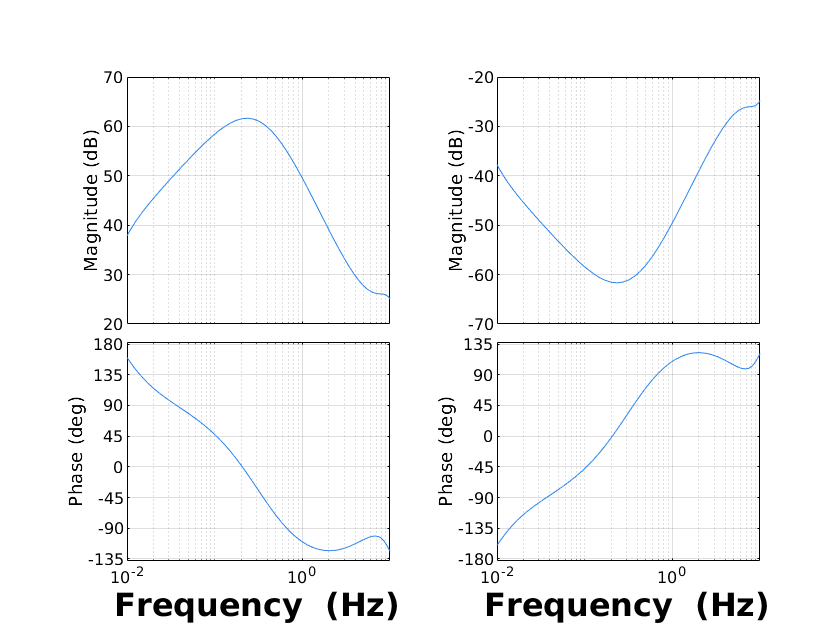

figure
subplot(1,2,1)
bodeplot(Hopen,bodeopts)
grid on
subplot(1,2,2)
bodeplot(S,bodeopts)
grid on